clear;

ProgressClassFile = "E:\YuLab\Work\GPS\Data\Gena\GPS_06_ThreeFPHoldSRT\GPSProgressClass_ThreeFPHoldSRT_GENA.mat";
saveFolder = fileparts(ProgressClassFile);
load(ProgressClassFile);
global B Label Ind

B = obj.BehavTable;
Ind = obj.Ind(B.Label=="Control" | B.Label=="Chemo", :);
B = B(B.Label=="Control" | B.Label=="Chemo", :);
Label = B.Label;

[~, ~, ind_rmv] = rmoutliers_custome(B.MovementTime);
B(ind_rmv, :) = [];
Ind(ind_rmv, :) = [];
Label(ind_rmv, :) = [];


modelspec = 'MovementTime ~ RT';

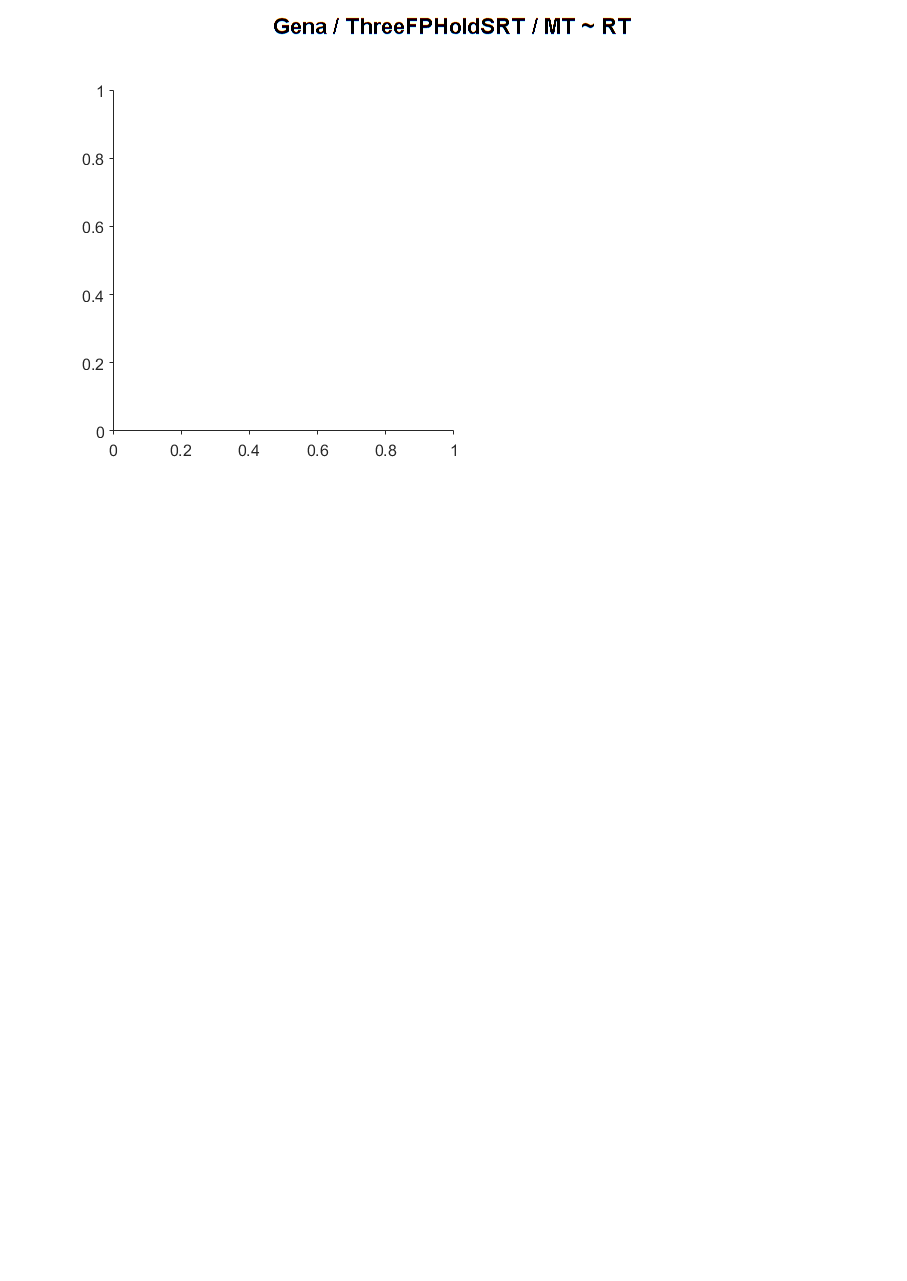

Error using classreg.regr.FitObject/compactNotAllowed
The 'Residuals' property is not
available from a compacted object.
Error in LinearModel/get_residuals (line 890)
            compactNotAllowed(model,'Residuals',true);
Error in classreg.regr.ParametricRegression/

fig_3fp = figure(31); clf(31);
set(gcf, 'unit', 'centimeters', 'position', [2 .7 16 22.6], 'paperpositionmode', 'auto', 'color', 'w');

uicontrol('Style', 'text', 'parent', 31, 'units', 'normalized', 'position', [0.2 0.95 0.6 0.04],...
    'string', obj.Subject+" / "+obj.Task+" / MT ~ RT", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

ax_size = [6 6];

% Left
% Short
ax_l_short = axes();
set(ax_l_short, "Units", "centimeters", "Position", [2+0*(.5+ax_size(1)), 2+2*(.5+ax_size(2)), ax_size], ...
    'nextplot', 'add', 'fontsize', 8, "TickDir", "out");
plot_MT_RT(ax_l_short, "L", "short", modelspec);

set(ax_l_short, "XTickLabel", [], "XLabel", []);

% Med
ax_l_med = axes();
set(ax_l_med, "Units", "centimeters", "Position", [2+0*(.5+ax_size(1)), 2+1*(.5+ax_size(2)), ax_size], ...
    'nextplot', 'add', 'fontsize', 8, "TickDir", "out");
plot_MT_RT(ax_l_med, "L", "med", modelspec);
set(ax_l_med, "XTickLabel", [], "XLabel", [], "Title", []);

% Long
ax_l_med = axes();
set(ax_l_med, "Units", "centimeters", "Position", [2+0*(.5+ax_size(1)), 2+0*(.5+ax_size(2)), ax_size], ...
    'nextplot', 'add', 'fontsize', 8, "TickDir", "out");
plot_MT_RT(ax_l_med, "L", "long", modelspec);
set(ax_l_med, "Title", []);

% Right
% Short
ax_l_short = axes();
set(ax_l_short, "Units", "centimeters", "Position", [2+1*(.5+ax_size(1)), 2+2*(.5+ax_size(2)), ax_size], ...
    'nextplot', 'add', 'fontsize', 8, "TickDir", "out");
plot_MT_RT(ax_l_short, "R", "short", modelspec);
set(ax_l_short, "XTickLabel", [], "XLabel", [], "YTickLabel", [], "YLabel", []);

% Med
ax_l_med = axes();
set(ax_l_med, "Units", "centimeters", "Position", [2+1*(.5+ax_size(1)), 2+1*(.5+ax_size(2)), ax_size], ...
    'nextplot', 'add', 'fontsize', 8, "TickDir", "out");
plot_MT_RT(ax_l_med, "R", "med", modelspec);
set(ax_l_med, "XTickLabel", [], "XLabel", [], "YTickLabel", [], "YLabel", [], "Title", []);

% Long
ax_l_med = axes();
set(ax_l_med, "Units", "centimeters", "Position", [2+1*(.5+ax_size(1)), 2+0*(.5+ax_size(2)), ax_size], ...
    'nextplot', 'add', 'fontsize', 8, "TickDir", "out");
plot_MT_RT(ax_l_med, "R", "long", modelspec);
set(ax_l_med, "YTickLabel", [], "YLabel", [], "Title", []);

savename = fullfile(saveFolder, "MT_RT_3FPs_" + obj.Subject);
print(fig_3fp, '-dpng', savename)

fig_all = figure(32); clf(32);
set(gcf, 'unit', 'centimeters', 'position', [2 .7 16 8.5], 'paperpositionmode', 'auto', 'color', 'w');

uicontrol('Style', 'text', 'parent', 32, 'units', 'normalized', 'position', [0.2 0.95 0.6 0.06],...
    'string', obj.Subject+" / "+obj.Task+" / MT ~ RT", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

ax_size = [6 6];
ax_l_all = axes();
set(ax_l_all, "Units", "centimeters", "Position", [2+0*(.5+ax_size(1)), 1.5, ax_size], ...
    'nextplot', 'add', 'fontsize', 8, "TickDir", "out");
plot_MT_RT(ax_l_all, "L", "all", modelspec)
ax_r_all = axes();
set(ax_r_all, "Units", "centimeters", "Position", [2+1*(.5+ax_size(1)), 1.5, ax_size], ...
    'nextplot', 'add', 'fontsize', 8, "TickDir", "out");
plot_MT_RT(ax_r_all, "R", "all", modelspec)
set(ax_r_all, "YTickLabel", [], "YLabel", []);
savename = fullfile(saveFolder, "MT_RT_total_" + obj.Subject);
print(fig_all, '-dpng', savename)

function plot_MT_RT(ax, port, fp, modelspec)

global B Label Ind

if fp=="all"
    D_control = B(Ind.("correct"+upper(port)) & Label=="Control", :);
    D_chemo = B(Ind.("correct"+upper(port)) & Label=="Chemo", :);
else
    D_control = B(Ind.("correct"+upper(port)) & Ind.(fp) & Label=="Control", :);
    D_chemo = B(Ind.("correct"+upper(port)) & Ind.(fp) & Label=="Chemo", :);
end

% Scatter
scatter(ax, D_control.RT, D_control.MovementTime, ...
    24, GPSColor.Control, "filled", "o", "MarkerFaceAlpha", 0.3, "MarkerEdgeAlpha", 0.3);
scatter(ax, D_chemo.RT, D_chemo.MovementTime, ...
    24, GPSColor.Treat  , "filled", "o", "MarkerFaceAlpha", 0.3, "MarkerEdgeAlpha", 0.3);

% Control fitting
D_control = sortrows(D_control, "RT");

mdl_control = fitlm(D_control, modelspec);
[MT_predict_control, CI_predict_control] = predict(mdl_control, D_control);
p_control = mdl_control.Coefficients.pValue(2);

% Chemo fitting
D_chemo = sortrows(D_chemo, "RT");

mdl_chemo = fitlm(D_chemo, modelspec);
[MT_predict_chemo, CI_predict_chemo] = predict(mdl_chemo, D_chemo);
p_chemo = mdl_chemo.Coefficients.pValue(2);

% Plot fit results
fill(ax, [D_control.RT; flip(D_control.RT)], [CI_predict_control(:, 1); flip(CI_predict_control(:, 2))], GPSColor.Control, "FaceAlpha", 0.2, "EdgeColor", "none");
fill(ax, [D_chemo.RT; flip(D_chemo.RT)], [CI_predict_chemo(:, 1); flip(CI_predict_chemo(:, 2))], GPSColor.Treat, "FaceAlpha", 0.2, "EdgeColor", "none");
plot(ax, D_control.RT, MT_predict_control, "Color", GPSColor.Control, "LineWidth", 2)
plot(ax, D_chemo.RT, MT_predict_chemo, "Color", GPSColor.Treat, "LineWidth", 2)

text(ax, 0.02, 0.98, fp, "HorizontalAlignment", "left")
text(ax, 0.5, 0.95, sprintf("p = %.2e", p_control), ...
    "Color", GPSColor.Control, "HorizontalAlignment", "right", "FontSize", 7, "FontWeight", "bold")
text(ax, 0.5, 0.9, sprintf("p = %.2e", p_chemo), ...
    "Color", GPSColor.Treat, "HorizontalAlignment", "right", "FontSize", 7, "FontWeight", "bold")

ax.XLabel.String = "Reaction time (s)";
ax.YLabel.String = "Movement time (s)";
ax.XLabel.FontWeight = "Bold";
ax.YLabel.FontWeight = "Bold";

switch upper(port)
    case "L"
        ax.Title.String = "Left";
        ax.Title.Color = GPSColor.PortL;
    case "R"
        ax.Title.String = "Right";
        ax.Title.Color = GPSColor.PortR;
end
ax.Title.FontWeight = "Bold";
ax.Title.FontSize = 11;

set(ax, 'XLim', [0 0.5], 'YLim', [0 1]);

end